# List Selection Dialog

The List Selection dialog is intended to prompt a user to select item(s) from a list, just like listdlg.

Create a figure:

fig = uifigure;
fig.Position(3:4) = [400 400];
fig.Name = "List Selection Dialog Example";

Create a modal dialog:

dlg = wt.dialog.ListSelection(fig);

Configure the dialog:

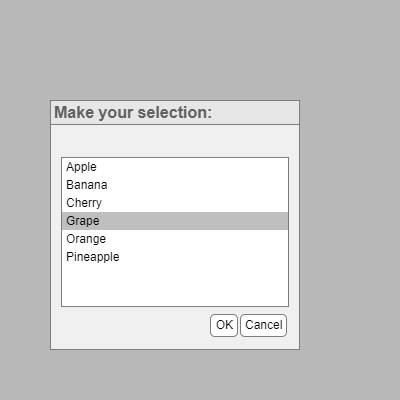

dlg.Title = "Make your selection:";
dlg.Size = [250 250]; % width, height
dlg.Items = ["Apple","Banana","Cherry","Grape","Orange","Pineapple"];
dlg.Value = "Grape"; % Set a default

Wait for output:

[output, lastAction] = dlg.waitForOutput()

output = struct with fields:
         Value: "Grape"
    ValueIndex: 4


lastAction = "ok"

close(fig)

*Copyright 2025 The MathWorks, Inc.*